初始化

%m
%% ver1
% R = 80*1e-3;
% r = 80*1e-3;
% L1 = 160*1e-3;
% L2 = 192*1e-3; 
% toolHight = 132*1e-3;
% z_p_min = 193.46*1e-3;

%% ver2
R = 104*1e-3;
r = 104*1e-3;
L1 = 208*1e-3;
L2 = 249.6*1e-3; 
toolHight = 136.8*1e-3;
z_p_min = 201.937*1e-3;

RRS_2RRU = RRS_2RRU_Basic(R, r, L1, L2, toolHight, z_p_min);

RRS_2RRU.z_p_max %max hight
RRS_2RRU.z_p_operation %operation hight
RRS_2RRU.delta_z_p %route

%% set spindle mass
spindle_mass = 5.25; %kg
spindle_mass_center_p = [0; 0; -46.3]*1e-3; %m
RRS_2RRU.setSpindleMass(spindle_mass, spindle_mass_center_p);

切削力

% 参数
Ks=791;
beta=71.6;
a_p = 1.2;
feedRate = 1650/60; %mm/s
d = 6;
Nt = 3;
omega = 9549;

% 理论交变切削力
steps = 100;
[Force_x, Force_y, Force, Torque, Power, t, phi] = getSlotMillingForce(Ks, beta, a_p, ...
                                                    feedRate, d, Nt, omega, steps, false);
Force_x_t = Force_x(1:0.5*steps);
Force_y_t = Force_y(1:0.5*steps);
Torque_t = Torque(1:0.5*steps);

simulink 计算工作空间各位型下各运动副最大约束反力，以及连杆最大拉压力、弯矩

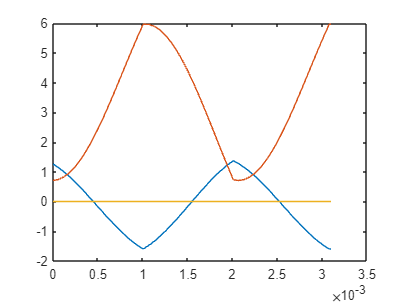

%simulink 导入模型关节角定义偏差
offsetThetaSim = @(theta) [pi-theta(1), theta(2), -theta(3)-pi/2];

%输入当前位型
cur_thetas = RRS_2RRU.setToInitPose();
thetas_sim = offsetThetaSim(cur_thetas);

%simulink 仿真结果
simOut = sim("RRS_2RRU_Robot_verify_ver2.slx");
figure
plot(out.tout, reshape(out.RRS_RR_R_cf(4:6,:,:), 3, size(out.RRS_RR_R_cf, 3)));